# Brain Scan Demo

*Koby Taswell and Ayush Garg*

This demo tests Optimal Hard Thresholding applied to each slice along Z axis.

filename = 'ABIDE_MRI_data.nii';

Vol = niftiread(filename);

[Nvol, Dvol, snrN, snrD] = TestVolume(Vol);


Original Signal to Noise Ratio at each Slice along Z axis

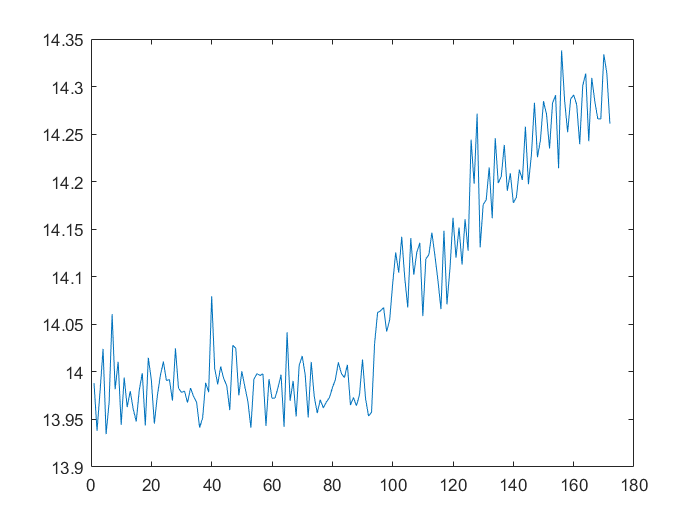

plot(snrN)

Denoised Signal to Noise Ratio at each slice along Z axis

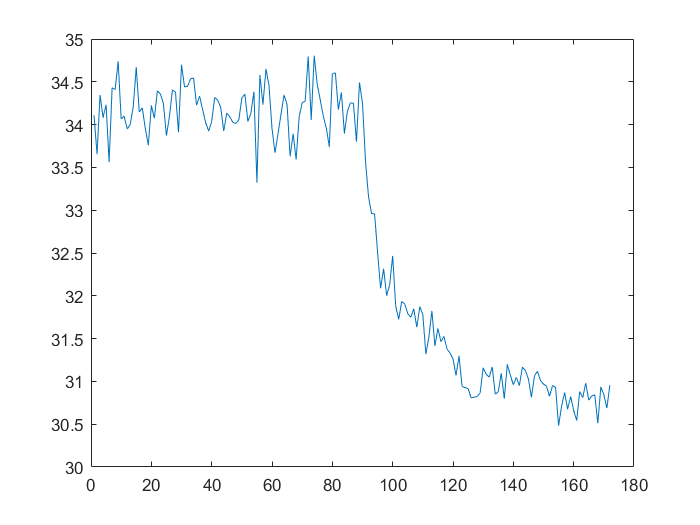

plot(snrD)

Amount of Signal to Noise Reduced by Arbitrary Optimal Hard Thresholding

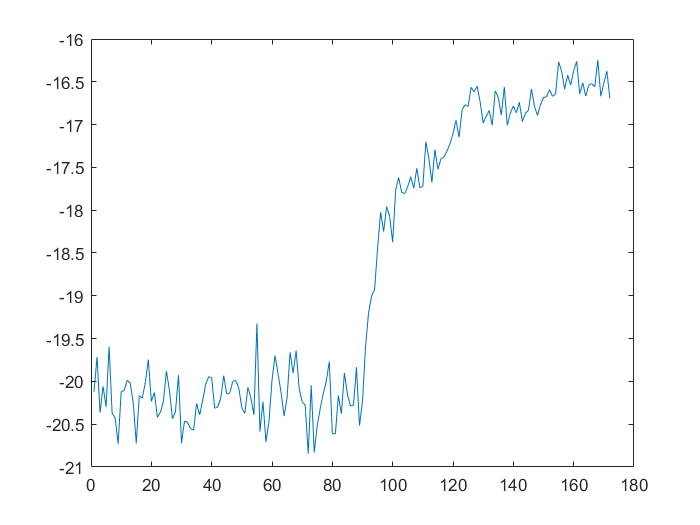

plot(snrN - snrD)

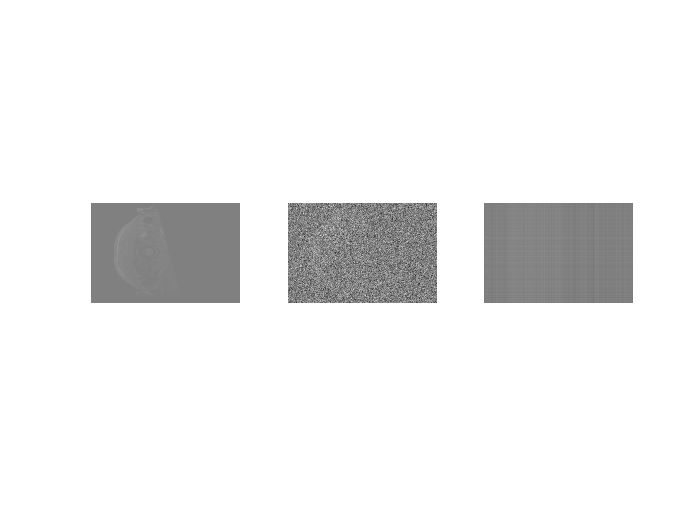

subplot(1,3,1)
imshow(Vol(:, :, 100));

subplot(1,3,2)
imshow(Nvol(:, :, 100));

subplot(1,3,3)
imshow(Dvol(:, :, 100))